2018 全国大学生数学建模竞赛


$$\frac{\partial }{\partial t}u_i \left(x,t\right)=\frac{\partial^2 }{\partial x^2 }u_i \left(x,t\right),0\le x\le x_i$$


边界条件


$$u_i \left(x,0\right)=T_h \ldotp T_h =37$$



$$u_i \left(0,t\right)=T_s ,T_s =75$$


相邻边界温度相等，温度梯度相等


$$\begin{array}{l}
u_i \left(x_i ,t\right)=u_{i+1} \left(x_i ,t\right)\\
\frac{\partial }{\partial t}u_i \left(x,t\right)|_{x=x_i } =\frac{\partial }{\partial t}u_{i+1} \left(x,t\right)|_{x=x_i } 
\end{array}$$


上述偏微分方程组离散化有


$$u^i \left(k,j\right)-u^i \left(k,j-1\right)=\frac{a\tau }{h}\left(u^i \left(k+1,j\right)-2u^i \left(k,j\right)+u^i \left(k-1,j\right)\right)$$


令$r=\frac{a\tau }{h},u^i \left(k,j\right)=u_{\textrm{kj}} ,j=j+1$有


$${u^i }_{\textrm{kj}+1} -{u^i }_{k,j} =r\left({u^i }_{k+1,j+1} -2{u^i }_{k,j+1} +{u^i }_{k-1,j+1} \right)$$


`移项有`


$${-r{u^i }_{k-1,j+1} +\left(1+2r\right)u^i }_{1j+1} -r{u^i }_{k,j+1} ={u^i }_{k,j} \;,k=1,,2,3,4\ldotp \ldotp \ldotp n-1$$


`对边界条件离散化有`


$${u^i }_{k,1} =T_h \ldotp T_h =37$$



$${u^i }_{1,j} =T_s ,T_s =75$$



$${u^i }_{x_i ,j} ={u^{i+1} }_{x_i -1,j}$$



$$k_1^i \frac{{u^i }_{x_i ,j} -{u^i }_{x_i -1,j} }{\Delta t}=k_2^i \frac{{u^{i+1} }_{x_i ,j} -{u^{i+1} }_{x_i -1,j} }{\Delta t}$$


进一步有


$${u^i }_{x_i ,j} =\frac{k_1^i }{k_1^i +k_2^i }\left({u^i }_{x_i -1,j} +{u^{i+1} }_{x_i ,j} \right)$$


综上有


$${-r_i {u^i }_{k-1,j+1} +\left(1+2r_i \right)u^i }_{1j+1} -r_i {u^i }_{k,j+1} ={u^i }_{k,j} \;,k=x_i +1,,2,3,4\ldotp \ldotp \ldotp x_{i+1} -1$$



$${u^i }_{k,1} =T_h \ldotp T_h =37$$



$${u^i }_{1,j} =T_s ,T_s =75$$



$${u^i }_{x_i ,j} =\frac{k_1^i }{k_1^i +k_2^i }\left({u^i }_{x_i -1,j} +{u^{i+1} }_{x_i ,j} \right)$$


%% 数据生成
clc,clear,close all
Data1=xlsread('CUMCM-2018-Problem-A-Chinese-Appendix.xlsx','附件1','B3:E6')

Data1 = 1.0e+03 *

    0.3000    1.3770    0.0001    0.0006
    0.8620    2.1000    0.0004       NaN
    0.0742    1.7260    0.0000    0.0036
    0.0012    1.0050    0.0000       NaN


Data2=xlsread('CUMCM-2018-Problem-A-Chinese-Appendix.xlsx','附件2','B3:B5403');
Data2=Data2(2:end,1);
tao=0.1;
all_time=90*60;
m=all_time/tao;
t=1:10:m;
tt=1:m;
temperature=interp1(t,Data2,tt,'spline');
save data.mat Data1 temperature

## 问题1

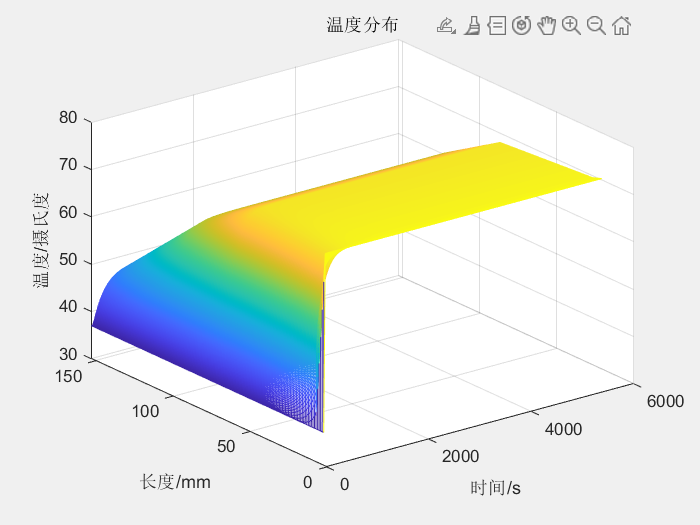

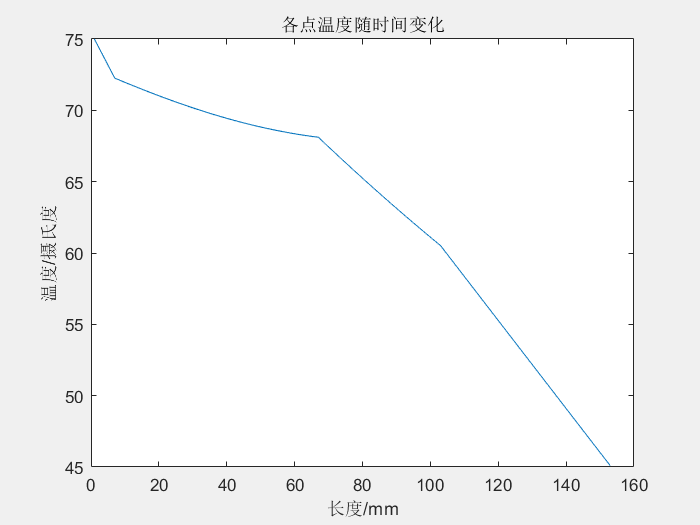

clc,clear,close all
load Data.mat
Data1(2,4)=6;
Data1(4,4)=5;
lamda=Data1(:,3);
a=lamda./(Data1(:,1).*Data1(:,2));
x=Data1(:,4);
%这个是数据十分关键
h=0.1;tao=0.1;
r=1e7*a*tao/h;
%环境温度
T=75;T0=37;%没有开始实验前温度都为人体温度
all_time=90*60;
m=all_time/tao;
N=round(x/h);
U=zeros(sum(N)+1,m);
U(:,1)=T0;%任何位置在没有进入实验之前都是体温
U(1,:)=T;%不论什么时刻与外界接触的面积都是环境温度
U(153,:)=temperature;%由于边界数据只有5400个 但是我们的时间数据需要540000个
%第一层
a={};b={};c={};
for i=1:4
    c1=-r(i)*ones(1,N(i)-2);
    b1=(1+2*r(i))*ones(1,N(i)-1);
    a1=[-r(i),c1];
    a{i}=a1;
    b{i}=b1;
    c{i}=c1;
end
for t=1:m-1
    i=t+1;
    %第一层 1:7
    d1=U(2:6,i-1);
    d1(1)=d1(1)+r(1)*U(1,i-1);
    d1(5)=d1(5)+r(1)*U(7,i-1);
    U(2:6,i)=After_Penalty(a{1,1}',b{1,1}',c{1,1}',d1);
    %第二层 8:67
    d2=U(8:66,i-1);
    d2(1)=d2(1)+r(2)*U(7,i-1);
    d2(59)=d2(59)+r(2)*U(67,i-1);
    U(8:66,i)=After_Penalty(a{1,2}',b{1,2}',c{1,2}',d2);
    %第三层 68:103
    d3=U(68:102,i-1);
    d3(1)=d3(1)+r(3)*U(67,i-1);
    d3(35)=d3(35)+r(3)*U(103,i-1);
    U(68:102,i)=After_Penalty(a{1,3}',b{1,3}',c{1,3}',d3);
    %第四层 69:153
    d4=U(104:152,i-1);
    d4(1)=d4(1)+r(4)*U(103,i-1);
    d4(49)=d4(49)+r(4)*U(153,i);
    U(104:152,i)=After_Penalty(a{1,4}',b{1,4}',c{1,4}',d4);
    % 各衔接层
    U(7,i)=(lamda(1)*U(6,i)+lamda(2)*U(8,i))/(lamda(1)+lamda(2));
    U(67,i)=(lamda(2)*U(66,i)+lamda(3)*U(68,i))/(lamda(2)+lamda(3)); 
    U(103,i)=(lamda(3)*U(102,i)+lamda(4)*U(104,i))/(lamda(3)+lamda(4));   
end
%每个10行采样1次
U1=U(:,1:10:m);
figure('name','温度变化')
set(gcf,'Visible','on');
mesh(U1);
title('温度分布')
ylabel('长度/mm');
xlabel('时间/s');
zlabel('温度/摄氏度');
figure('name','各点温度随时间变化')
for i=1:m/10
    set(gcf,'Visible','on');
    plot(U1(:,i));
    title('各点温度随时间变化')
    ylabel('温度/摄氏度');
    xlabel('长度/mm');
    drawnow;
end

A=[1-1/2,1/2-1,0;
    -3/5,0,3/5-1;
    -7/11,0,1];
b=[1;1;1];
x=b\A;
p3=7/11;p2=3/5;p1=1/2;
a0=1/(1-p3)+1/((1-p3)*(1-p2))+1/((1-p3)*(1-p2)*(1-p1));
